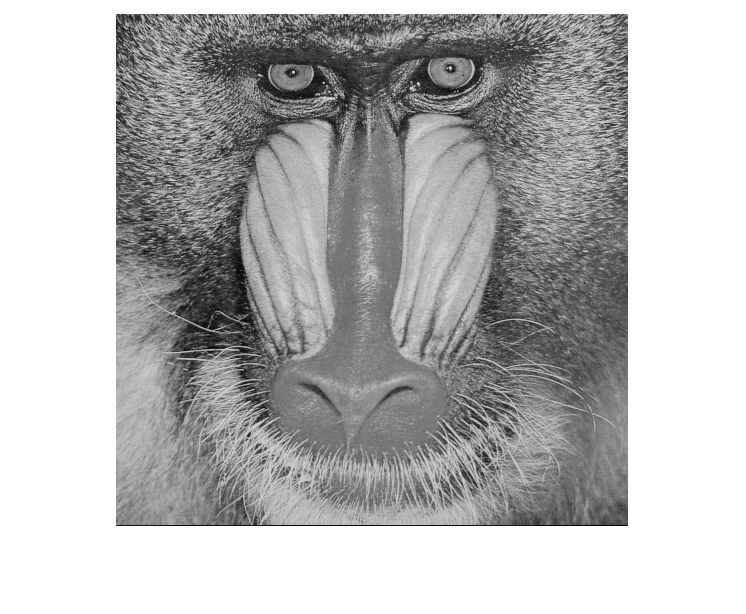

img = imread("../materials/Baboon.tif");
[M, N] = size(img);
imshow(img)

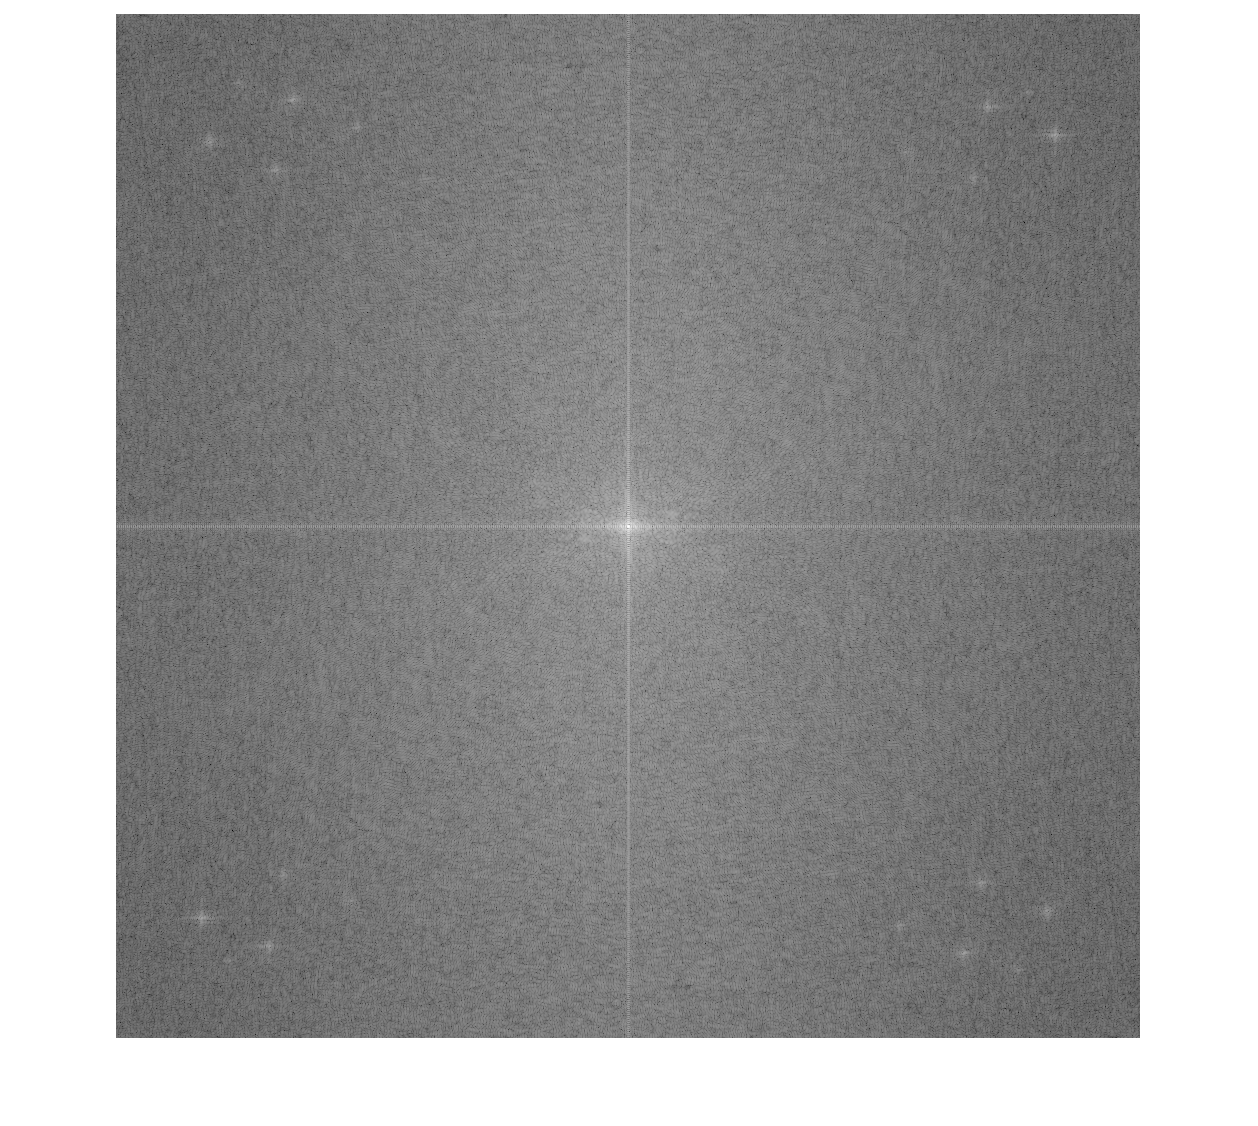

shift_img = double(img) .* (-1).^((1:M)' + (1:N));
pad_img = padarray(shift_img, [M, N], 0, "post"); % pad the image to the top left
fft_img = fft2(pad_img);
[P, Q] = size(fft_img);
imshow(real(log(fft_img)), [])

D0 = 30;
% use Gaussian_filter
Gaussian_filter = zeros(size(pad_img));
for x=1:P
    for y=1:Q
        Gaussian_filter(x, y) = 1 - exp(-((x-P/2)^2+(y-Q/2)^2)/(2*D0^2));
    end
end

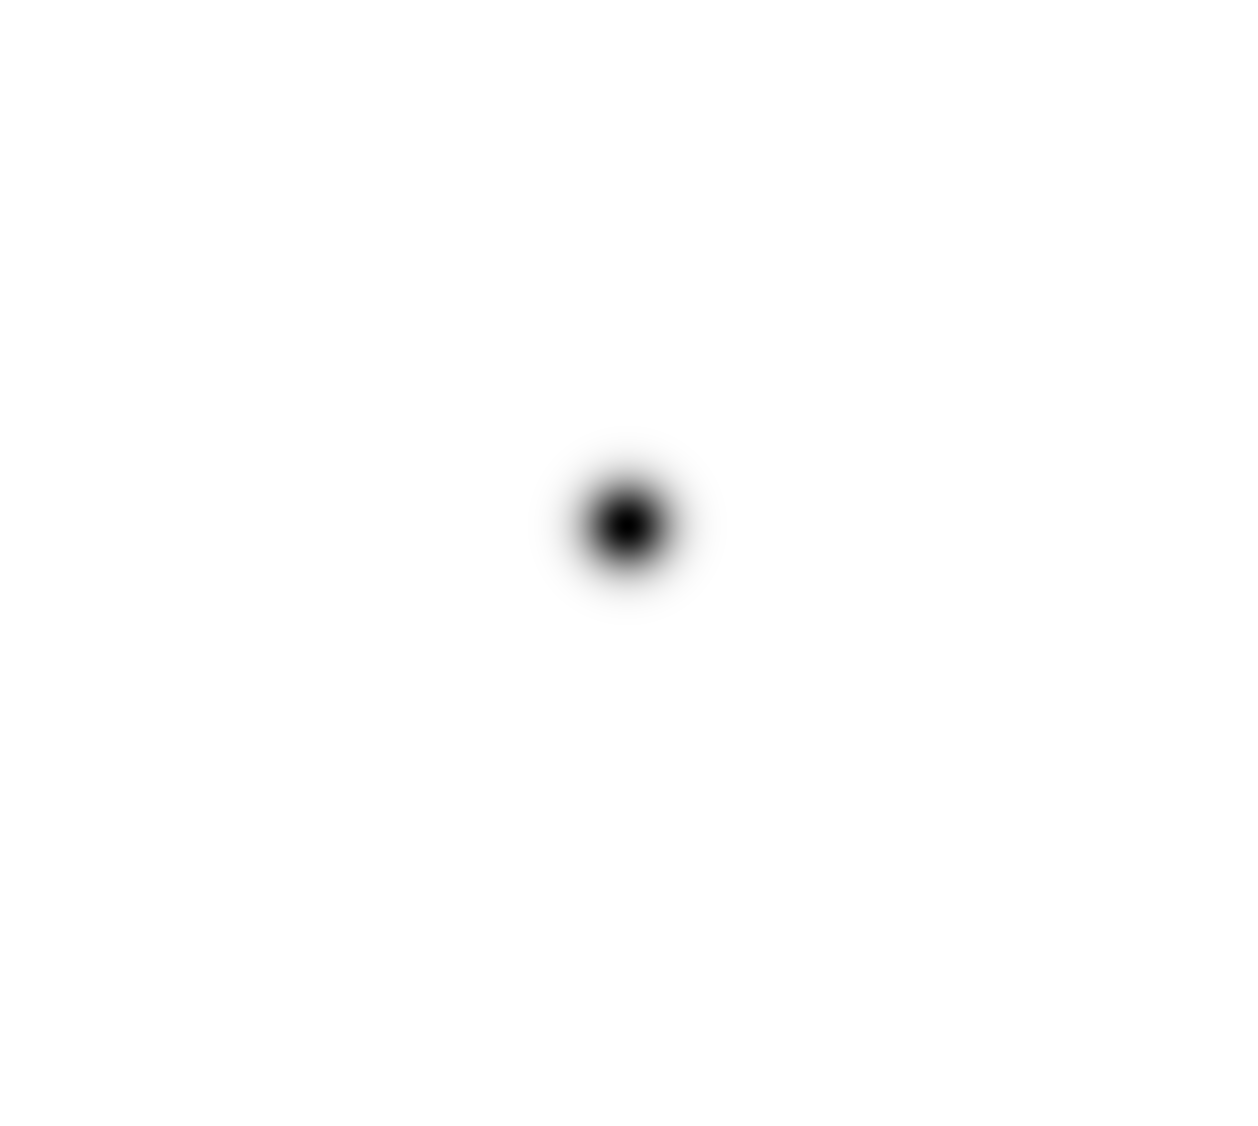

imshow(Gaussian_filter,[])

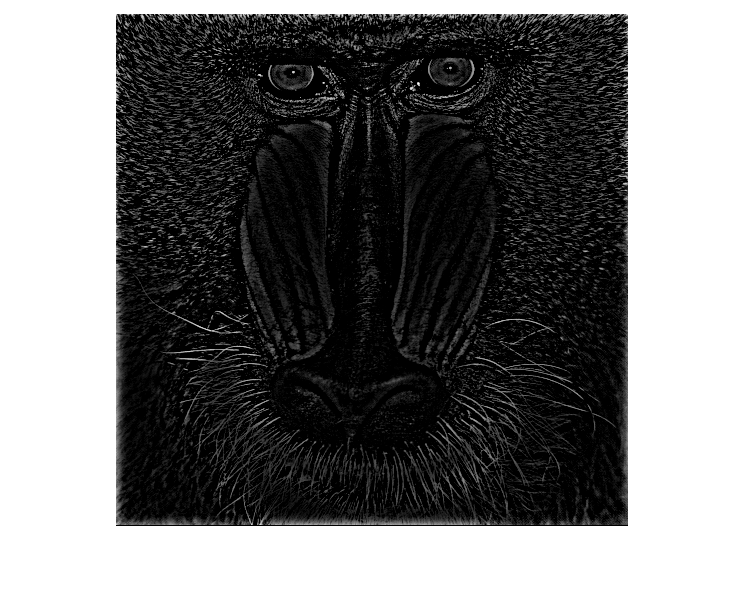

result_freq = fft_img .* Gaussian_filter;
result = real(ifft2(result_freq));
result = result(1:M, 1:N) .* (-1).^((1:M)' + (1:N));
% set all value < 0 to 0
result(result<0) = 0;
imshow(result, [])